# Fibit sleep data analysis

An example of [Exploratory data analysis](https://en.wikipedia.org/wiki/Exploratory_data_analysis) in [MATLAB](http://www.mathworks.com)

## Importing the data

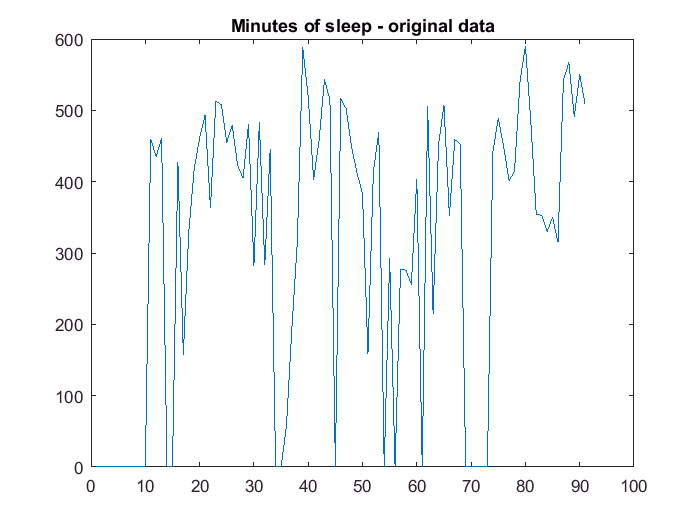

[Date,MinSleep,MinWakeup,WakeupCount,MinInBed] = importsleep('fitbit_export_sleep_jan_mar.csv',2, 92);
plot(MinSleep)
title('Minutes of sleep - original data');

## Cleaning the data

The data contains several records with '0' values. The person did not sleep on that day at all? We do not think so. We need to drop the invalid records. Since we know the person did not have any sleepless nights, we'll drop all records with less than 200 minutes.

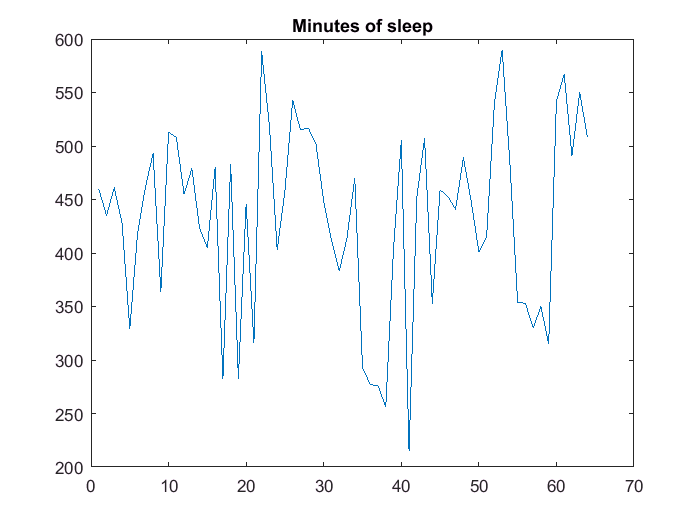

idx = MinSleep > 200;

MinSleep = MinSleep(idx);
Date = Date(idx);
MinWakeup = MinWakeup(idx);
WakeupCount = WakeupCount(idx);
MinInBed = MinInBed(idx);

plot(MinSleep)
title('Minutes of sleep');

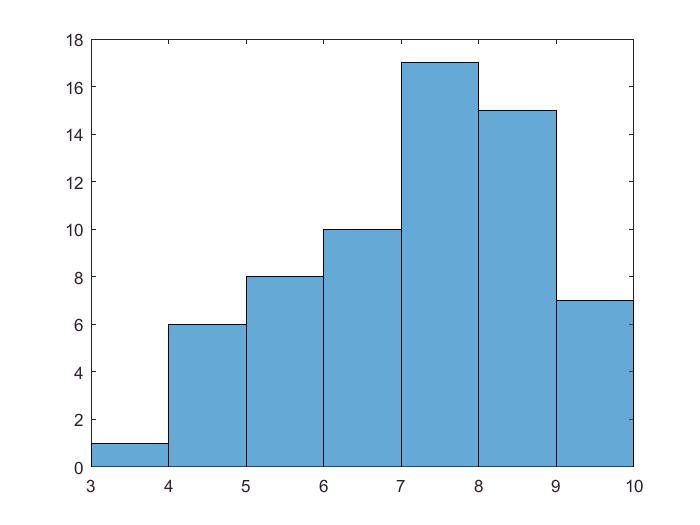

histogram(MinSleep/60);